clc;
clear all;

% syms e1 e1_dot e2 e2_dot C_y I_z v_xb v_yb L tau u_delta m
v_xb = 2.0

v_xb = 2

tau= 0.1

tau = 0.1000

L = 0.4

L = 0.4000

C_y = 100

C_y = 100

m = 11.5

m = 11.5000

I_z = 0.5

I_z = 0.5000

A = [0, 1, 0, 0;
    0, C_y/(m*v_xb), C_y/m, 0;
    0, 0, 0, 1;
    0, 0, 0, (-L^2 * C_y)/(2*I_z*v_xb)]

A =          0    1.0000         0         0
         0    4.3478    8.6957         0
         0         0         0    1.0000
         0         0         0   -8.0000



B = [0, C_y/m, 0, (C_y*L)/(2*I_z)].'

B =          0
    8.6957
         0
   40.0000



C = [0, -v_xb, 0, (-L^2 * C_y)/(2*I_z*v_xb)]

C =          0   -2.0000         0   -8.0000


D = [0]

D = 0


% R = [B, A*B, A^2 *B, A^3 * B];
% [u, s, v] = svd(R, "econ")
% rank(R)
% First Pole Placement
% sys = ss(A, B, C, D, 0.01)
% eig(A)
% P = [-1, -2, -3, -4]
% K = place(A, B, P)
open = eig(A)

open =          0
    4.3478
         0
   -8.0000


systemOpenLoop=ss(A,B,C,D)

systemOpenLoop =
 
  A = 
          x1     x2     x3     x4
   x1      0      1      0      0
   x2      0  4.348  8.696      0
   x3      0      0      0      1
   x4      0      0      0     -8
 
  B = 
          u1
   x1      0
   x2  8.696
   x3      0
   x4     40
 
  C = 
       x1  x2  x3  x4
   y1   0  -2   0  -8
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


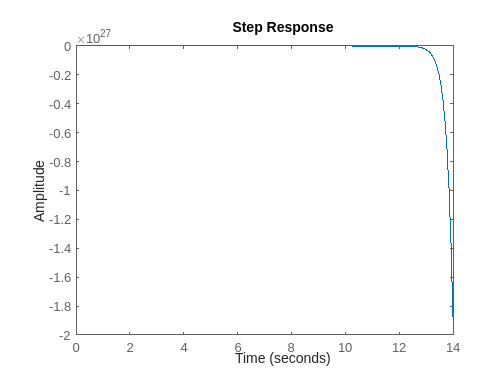

step(systemOpenLoop)

rank(ctrb(A, B))

ans = 4

% zeros(4,1)
A_aug = [A, zeros(4,1);
         -C, 0]

A_aug =          0    1.0000         0         0         0
         0    4.3478    8.6957         0         0
         0         0         0    1.0000         0
         0         0         0   -8.0000         0
         0    2.0000         0    8.0000         0


B_aug = [B; 0]

B_aug =          0
    8.6957
         0
   40.0000
         0


rank(ctrb(A_aug, B_aug))

ans = 4


B_r = [zeros(2,1);1];
des_poles = [3*open; 
            10*min(open)]

des_poles =          0
   13.0435
         0
  -24.0000
  -80.0000


% K = place(A_aug, B_aug, des_poles)
% Acl=A_aug-B_aug*K
% poles_place=eig(Acl)
% 
% sort(des_poles)-sort(poles_place)
% 
% Ccl=[C 0]
% Dcl=[]
% systemCloseLoop=ss(Acl,Br,Ccl,Dcl)



clc;
clear all;

v_xb = 2.0

v_xb = 2

tau= 0.1

tau = 0.1000

L = 0.4

L = 0.4000

C_y = 100

C_y = 100

m = 11.5

m = 11.5000

I_z = 0.5

I_z = 0.5000

A = [[0, 1, 0, 0];
    [0, -C_y/(m*v_xb), C_y/m, 0];
    [0, 0, 0, 1];
    [0, 0, 0, (-L^2 * C_y)/(2*I_z*v_xb)]]

A =          0    1.0000         0         0
         0   -4.3478    8.6957         0
         0         0         0    1.0000
         0         0         0   -8.0000


rank(A)

ans = 3

B = [0, C_y/m, 0, (C_y*L)/(2*I_z)].'

B =          0
    8.6957
         0
   40.0000



C = [0, -v_xb, 0, (-L^2 * C_y)/(2*I_z*v_xb)]

C =          0   -2.0000         0   -8.0000


D = [0]

D = 0


R = [B, A*B, A^2 *B, A^3 * B];

% k = sym('k', [4 4])
% e = sym('e', [4 1])

sys = ss(A,B,C,D)

sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0  -4.348   8.696       0
   x3       0       0       0       1
   x4       0       0       0      -8
 
  B = 
          u1
   x1      0
   x2  8.696
   x3      0
   x4     40
 
  C = 
       x1  x2  x3  x4
   y1   0  -2   0  -8
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


poles = [-5.0, -5.5, -6.0, -6.5]

poles =    -5.0000   -5.5000   -6.0000   -6.5000


K = place(A, B, poles)

K =     3.0834    0.7063    1.6853    0.1128


Acl = A-B*K

Acl =          0    1.0000         0         0
  -26.8125  -10.4892   -5.9591   -0.9806
         0         0         0    1.0000
 -123.3375  -28.2504  -67.4116  -12.5108



closesys = ss(Acl, B, C, D)

closesys =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2   -26.81   -10.49   -5.959  -0.9806
   x3        0        0        0        1
   x4   -123.3   -28.25   -67.41   -12.51
 
  B = 
          u1
   x1      0
   x2  8.696
   x3      0
   x4     40
 
  C = 
       x1  x2  x3  x4
   y1   0  -2   0  -8
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


clc;
clear all;
syms e1 e1_dot e2 e2_dot C_y I_z v_xb v_yb L tau u_delta m 
e_vec = [e1 e1_dot e2 e2_dot].'

$$e\_vec = \left(\begin{array}{c} e_{1}\\ e_{\dot{1}}\\ e_{2}\\ e_{\dot{2}} \end{array}\right)$$

A = [[0, 1, 0, 0];
    [0, -C_y/(m*v_xb), C_y/m, 0];
    [0, 0, 0, 1];
    [0, 0, 0, (-L^2 * C_y)/(2*I_z*v_xb)]]

$$A = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & -\frac{C_{y}}{m\,v_{\mathrm{xb}}} & \frac{C_{y}}{m} & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & 0 & -\frac{C_{y}\,L^{2}}{2\,I_{z}\,v_{\mathrm{xb}}} \end{array}\right)$$

B = [0, C_y/m, 0, (C_y*L)/(2*I_z)].'

$$B = \left(\begin{array}{c} 0\\ \frac{C_{y}}{m}\\ 0\\ \frac{C_{y}\,L}{2\,I_{z}} \end{array}\right)$$


K = sym('K',[1,4])

$$K = \left(\begin{array}{cccc} K_{1} & K_{2} & K_{3} & K_{4} \end{array}\right)$$

A*e_vec

$$ans = \left(\begin{array}{c} e_{\dot{1}}\\ \frac{C_{y}\,e_{2}}{m}-\frac{C_{y}\,e_{\dot{1}}}{m\,v_{\mathrm{xb}}}\\ e_{\dot{2}}\\ -\frac{C_{y}\,L^{2}\,e_{\dot{2}}}{2\,I_{z}\,v_{\mathrm{xb}}} \end{array}\right)$$

(A-B*K)

$$ans = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ -\frac{C_{y}\,K_{1}}{m} & -\frac{C_{y}}{m\,v_{\mathrm{xb}}}-\frac{C_{y}\,K_{2}}{m} & \frac{C_{y}}{m}-\frac{C_{y}\,K_{3}}{m} & -\frac{C_{y}\,K_{4}}{m}\\ 0 & 0 & 0 & 1\\ -\frac{C_{y}\,K_{1}\,L}{2\,I_{z}} & -\frac{C_{y}\,K_{2}\,L}{2\,I_{z}} & -\frac{C_{y}\,K_{3}\,L}{2\,I_{z}} & -\frac{C_{y}\,L^{2}}{2\,I_{z}\,v_{\mathrm{xb}}}-\frac{C_{y}\,K_{4}\,L}{2\,I_{z}} \end{array}\right)$$


clc;
clear all;

v_xb = 2.0

v_xb = 2

tau= 0.1

tau = 0.1000

L = 0.4

L = 0.4000

C_y = 100

C_y = 100

m = 11.5

m = 11.5000

I_z = 0.5

I_z = 0.5000

n = 4

n = 4

A = [0, 1, 0, 0;
    0, C_y/(m*v_xb), C_y/m, 0;
    0, 0, 0, 1;
    0, 0, 0, (-L^2 * C_y)/(2*I_z*v_xb)]

A =          0    1.0000         0         0
         0    4.3478    8.6957         0
         0         0         0    1.0000
         0         0         0   -8.0000


A_aug = [A, zeros(n, n);
         eye(n), zeros(n, n)]

A_aug =          0    1.0000         0         0         0         0         0         0
         0    4.3478    8.6957         0         0         0         0         0
         0         0         0    1.0000         0         0         0         0
         0         0         0   -8.0000         0         0         0         0
    1.0000         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0
         0         0         0    1.0000         0         0         0         0


B = [0, C_y/m, 0, (C_y*L)/(2*I_z)].'

B =          0
    8.6957
         0
   40.0000


B_aug = [B; zeros(n, 1)]

B_aug =          0
    8.6957
         0
   40.0000
         0
         0
         0
         0


cont = ctrb(A_aug, B_aug)

cont = 1.0e+07 *

         0    0.0000    0.0000    0.0001   -0.0001    0.0020   -0.0092    0.1026
    0.0000    0.0000    0.0001   -0.0001    0.0020   -0.0092    0.1026   -0.6939
         0    0.0000   -0.0000    0.0003   -0.0020    0.0164   -0.1311    1.0486
    0.0000   -0.0000    0.0003   -0.0020    0.0164   -0.1311    1.0486   -8.3886
         0         0    0.0000    0.0000    0.0001   -0.0001    0.0020   -0.0092
         0    0.0000    0.0000    0.0001   -0.0001    0.0020   -0.0092    0.1026
         0         0    0.0000   -0.0000    0.0003   -0.0020    0.0164   -0.1311
         0    0.0000   -0.0000    0.0003   -0.0020    0.0164   -0.1311    1.0486


rank(cont)

ans = 5